wp = 0.2*pi;
M = input("Enter order of filter: ");
h_hann = fir1(M, wp/pi, hann(M+1));
h_hamm = fir1(M, wp/pi, hamming(M+1));
h_blackman = fir1(M, wp/pi, blackman(M+1));
h_bartlett = fir1(M, wp/pi, bartlett(M+1))

h_bartlett =          0   -0.0005   -0.0018   -0.0028   -0.0025    0.0000    0.0042    0.0086    0.0106    0.0080   -0.0000   -0.0120   -0.0239   -0.0295   -0.0229    0.0000    0.0393    0.0901    0.1432    0.1868    0.2102    0.1868    0.1432    0.0901    0.0393    0.0000   -0.0229   -0.0295   -0.0239   -0.0120   -0.0000    0.0080    0.0106    0.0086    0.0042    0.0000   -0.0025   -0.0028   -0.0018   -0.0005         0


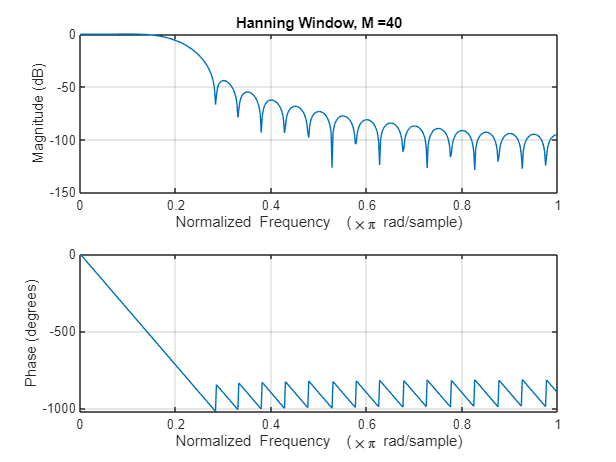

freqz(h_hann, 1, 512); title(['Hanning Window, M =', int2str(M)]);

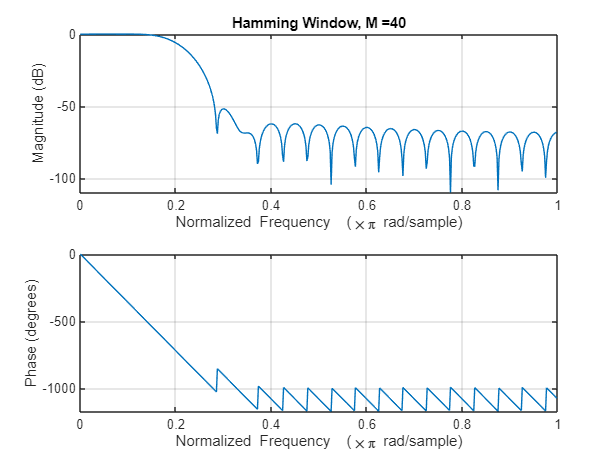

figure;
freqz(h_hamm, 1, 512); title(['Hamming Window, M =', int2str(M)]);

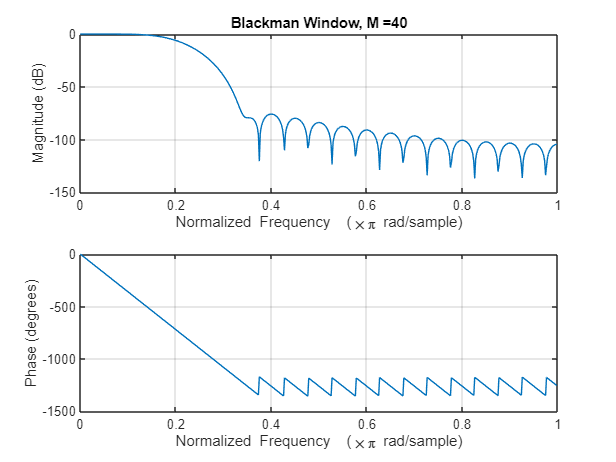

figure;
freqz(h_blackman, 1, 512); title(['Blackman Window, M =', int2str(M)]);

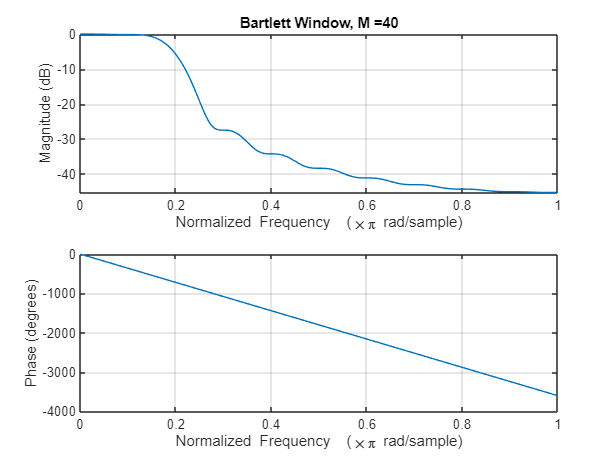

figure;
freqz(h_bartlett, 1, 512); title(['Bartlett Window, M =', int2str(M)]);

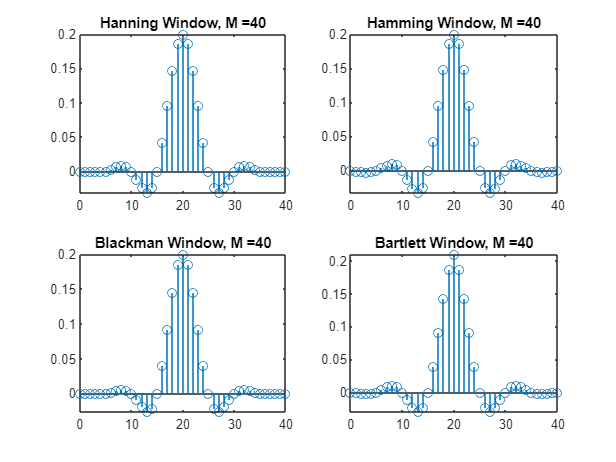

figure;
n =0 : M;
subplot(2,2,1), stem(n, h_hann);
title(['Hanning Window, M =', int2str(M)]);
subplot(2,2,2), stem(n, h_hamm);
title(['Hamming Window, M =', int2str(M)]);
subplot(2,2,3), stem(n, h_blackman);
title(['Blackman Window, M =', int2str(M)]);
subplot(2,2,4), stem(n, h_bartlett);
title(['Bartlett Window, M =', int2str(M)]);

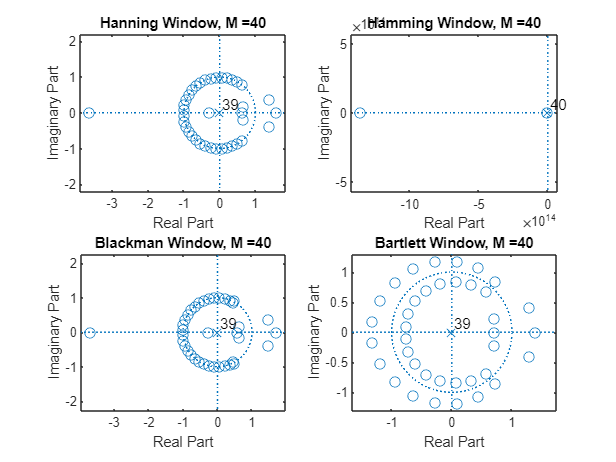

figure;
subplot(2,2,1), zplane(h_hann);
title(['Hanning Window, M =', int2str(M)]);
subplot(2,2,2), zplane(h_hamm);
title(['Hamming Window, M =', int2str(M)]);
subplot(2,2,3), zplane(h_blackman);
title(['Blackman Window, M =', int2str(M)]);
subplot(2,2,4), zplane(h_bartlett);
title(['Bartlett Window, M =', int2str(M)]);